clear 
% 生成实际PV,WT数据以及相关误差数据
load('data_generation_20250727.mat');
input=data_generation;

input.Nc=100;
%风电的每个时刻的单位出力
input.p_wt_unit=4e3*[0.321631879,0.322343454,0.258301708,0.272468518,0.134131879,0.097770398,0.055218216,...
               0.096774194,0.060412713,0.129981025,0.073363378,0.057779886,0.024193548,0.111148008,...
               0.147509488,0.104743833,0.178961101,0.360768501,0.390014231,0.290322581,0.290322581,...
               0.323410816,0.279569892,0.267552182];
%光伏的每个时刻的单位出力
input.p_pv_unit=4e3*[0,0,0,0,0,0,0.106973435,0.136622391,0.177182163,0.229127135,0.314444972,0.431570209,...
               0.541437381,0.626185958,0.553152493,0.444540279,0.3342821,0.219165085,0.115275142,0,...
               0,0,0,0];
%负荷
[load_e,load_g,load_h,load_H2_m]=LOAD_ehH;
input.load_e=load_e;
input.load_g=load_g;
input.load_h=load_h;
input.load_H2_m=load_H2_m;
input.price_pun=1.08*1.5;%偏差惩罚成本

%结果
[result] = DAY_ope5(input);

求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功
求解成功




a1=sum(result.Cost3_all)

a1 = 3.7593e+06

E_one=result.E_one;                   %一阶段电力平衡
h_one=result.h_one;                   %一阶段热力平衡
H_one=result.H_one;                   %一阶段氢质量平衡
E_two=result.E_two;                   %二阶段电力平衡
H_two=result.H_two;                   %二阶段氢质量平衡
m_shs_two=result.m_shs_two;           %储氢罐储氢量

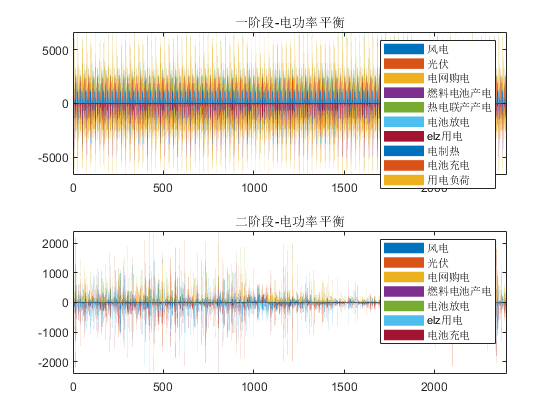

figure(1)
% 子图 1 - 电功率平衡一阶段
subplot(2, 1, 1);
bar(E_one, 'stacked');
title('一阶段-电功率平衡');
legend('风电','光伏','电网购电','燃料电池产电','热电联产产电','电池放电','elz用电','电制热','电池充电','用电负荷');

% 子图 2 - 电功率平衡二阶段
subplot(2, 1, 2);
bar(E_two, 'stacked');
title('二阶段-电功率平衡');
legend('风电','光伏','电网购电','燃料电池产电','电池放电','elz用电','电池充电');
hold off

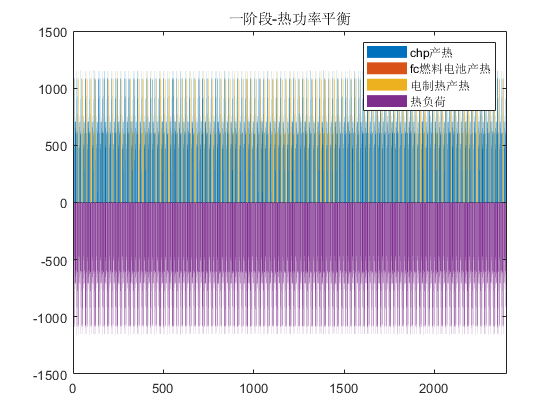

figure(2)
bar(h_one,'stacked');
title('一阶段-热功率平衡');
legend('chp产热','fc燃料电池产热','电制热产热','热负荷');
hold off

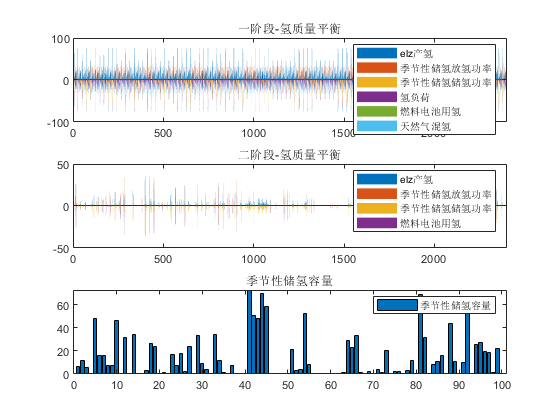

figure(3)
% 子图 1 - 氢功率平衡一阶段
subplot(3, 1, 1);
bar(H_one,'stacked');
%hold on
title('一阶段-氢质量平衡');
legend('elz产氢','季节性储氢放氢功率','季节性储氢储氢功率','氢负荷','燃料电池用氢','天然气混氢');

% 子图 2 - 氢功率平衡二阶段
subplot(3, 1, 2);
bar(H_two,'stacked');
%hold on
title('二阶段-氢质量平衡');
legend('elz产氢','季节性储氢放氢功率','季节性储氢储氢功率','燃料电池用氢');

% 子图 3 - 季节性储氢容量
subplot(3, 1, 3);
bar(result.m_shs_ini_all,'stacked');
%hold on
title('季节性储氢容量');
legend('季节性储氢容量');
hold off

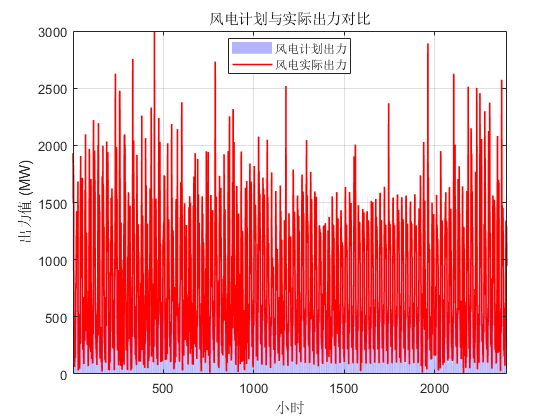



figure(4);
% 绘制风电计划出力和实际出力
bar(result.p_wt_unit_plan_all, 'FaceColor', [0.5 0.5 1], 'FaceAlpha', 0.6, 'BarWidth', 0.8, 'DisplayName', '风电计划出力'); 
hold on;
plot(input.p_wt_unit_real_all, 'r-', 'LineWidth', 1.2, 'DisplayName', '风电实际出力');
ylabel('出力值 (MW)');
xlabel('小时');
title('风电计划与实际出力对比');
legend('show', 'Location', 'best');
grid on;
xlim([0.5, length(result.p_wt_unit_plan_all)+0.5]); % 优化X轴范围
hold off;

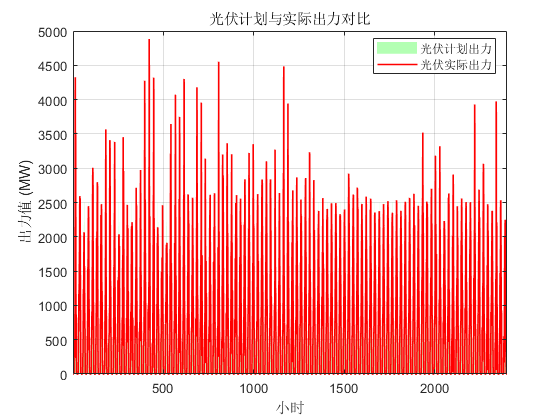


figure(5);
% 绘制光伏计划出力和实际出力
bar(result.p_pv_unit_plan_all, 'FaceColor', [0.5 1 0.5], 'FaceAlpha', 0.6, 'BarWidth', 0.8, 'DisplayName', '光伏计划出力'); 
hold on;
plot(input.p_pv_unit_real_all, 'r-', 'LineWidth', 1.2, 'DisplayName', '光伏实际出力');
ylabel('出力值 (MW)');
xlabel('小时');
title('光伏计划与实际出力对比');
legend('show', 'Location', 'best');
grid on;
xlim([0.5, length(result.p_pv_unit_plan_all)+0.5]); % 优化X轴范围
hold off;




%成本变化趋势

% 全部按照
%经济对比1   即根据实际预测效果进行对比
[~,~,Cost_onestage_unit_value_day,~,~,~,~]=onestage_Cost1_unit_20231013(0,input.p_pv_unit,input.p_wt_unit);

Default variable names x1, x2 ... being created.
Default row names c1, c2 ... being created.
CPXPARAM_Simplex_Display                         2
CPXPARAM_Barrier_Display                         2
CPXPARAM_MIP_Tolerances_MIPGap                   0.10000000000000001
Tried aggregator 2 times.
MIP Presolve eliminated 772 rows and 508 columns.
MIP Presolve modified 96 coefficients.
Aggregator did 25 substitutions.
Reduced MIP has 166 rows, 355 columns, and 729 nonzeros.
Reduced MIP has 70 binaries, 0 generals, 0 SOSs, and 0 indicators.
Presolve time = 0.01 sec. (1.51 ticks)
Found incumbent of value 0.325063 after 0.01 sec. (2.45 ticks)
Probing time = 0.00 sec. (0.04 ticks)
Tried aggregator 1 time.
MIP Presolve eliminated 47 rows and 70 columns.
Reduced MIP has 119 rows, 285 columns, and 545 nonzeros.
Reduced MIP has 0 binaries, 0 generals, 0 SOSs, and 0 indicators.
Presolve time = 0.00 sec. (0.22 ticks)
Tried aggregator 1 time.
Reduced MIP has 119 rows, 285 columns, and 545 nonzeros.
Reduced

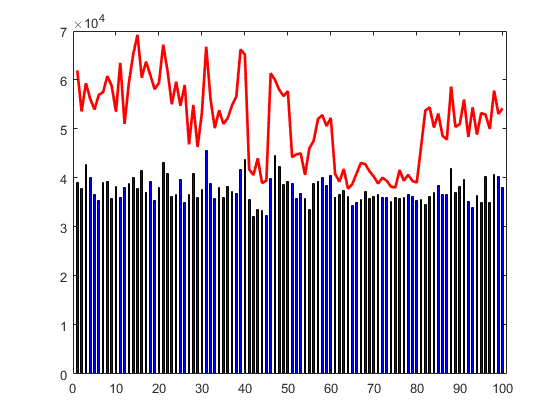

Cost_onestage_unit_value_day=ones(1,input.Nc)*Cost_onestage_unit_value_day;
Cost_duibi=Cost_onestage_unit_value_day+input.a1_pun_cost_all+input.a2_pun_cost_all;
a=sum(result.Cost3_all);

figure(6)
x = 1:numel(result.Cost3_all);
bar(x,result.Cost3_all, 'b', 'BarWidth', 0.4);
hold on;
% 创建折线图
plot(x,Cost_duibi, 'r', 'LineWidth', 2);